t = 0:0.05:1

t =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


f = 10 .* cos(2 * pi * t)

f =    10.0000    9.5106    8.0902    5.8779    3.0902    0.0000   -3.0902   -5.8779   -8.0902   -9.5106  -10.0000   -9.5106   -8.0902   -5.8779   -3.0902   -0.0000    3.0902    5.8779    8.0902    9.5106   10.0000


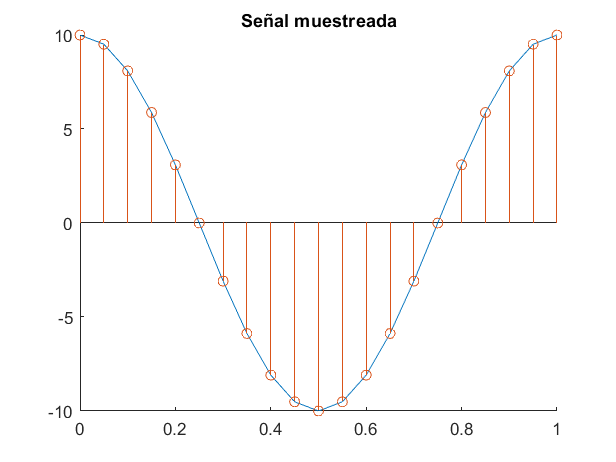


fig = figure;

hold on
plot(t, f)
stem(t, f)
title("Señal muestreada")

## Cuantización usando el truncamiento

f_q = floor(f)

f_q =     10     9     8     5     3     0    -4    -6    -9   -10   -10   -10    -9    -6    -4    -1     3     5     8     9    10


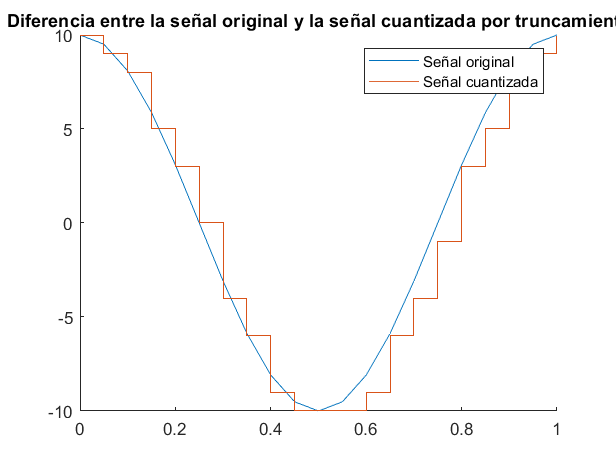


figure

hold on
plot(t, f)
stairs(t, f_q)


legend("Señal original", "Señal cuantizada")
title("Diferencia entre la señal original y la señal cuantizada por truncamiento")


err = sum(f - f_q) / 20

err = 0.4500

## Cuantización usando el redondeo

f_q = round(f)

f_q =     10    10     8     6     3     0    -3    -6    -8   -10   -10   -10    -8    -6    -3     0     3     6     8    10    10


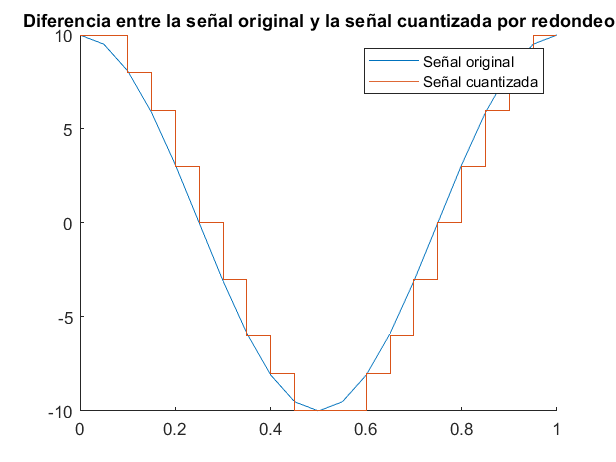


figure

hold on
plot(t, f)
stairs(t, f_q)


legend("Señal original", "Señal cuantizada")
title("Diferencia entre la señal original y la señal cuantizada por redondeo")



err = abs(sum(f - f_q)) / 20

err = 8.3267e-16

## Cuantización usando el redondeo (pero con un decimal de precisión)

f_q = round(f, 1)

f_q =    10.0000    9.5000    8.1000    5.9000    3.1000         0   -3.1000   -5.9000   -8.1000   -9.5000  -10.0000   -9.5000   -8.1000   -5.9000   -3.1000         0    3.1000    5.9000    8.1000    9.5000   10.0000


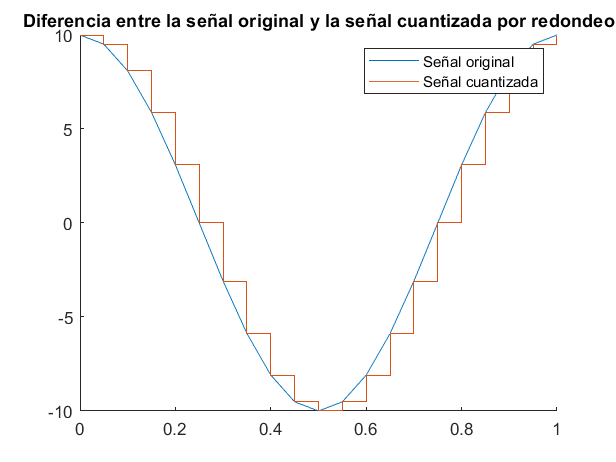


figure

hold on
plot(t, f)
stairs(t, f_q)


legend("Señal original", "Señal cuantizada")
title("Diferencia entre la señal original y la señal cuantizada por redondeo")



err = abs(sum(f - f_q)) / 20

err = 8.3839e-16